**HW_1**

Here system equation as              $\begin{array}{l}
\dot{\;x} =y\\
\dot{y\;} =-x\;\;\;\;\;x\left(0\right)=1\;,y\left(0\right)=0\;\;,t\in \left\lbrack 0,10\pi \;\right\rbrack 
\end{array}$

1)   $\left\lbrack x\left(0\right),y\left(0\right)\right\rbrack \;=\left\lbrack 0,1\right\rbrack \;,\left\lbrack 0,-1\right\rbrack ,\left\lbrack -1,0\right\rbrack$

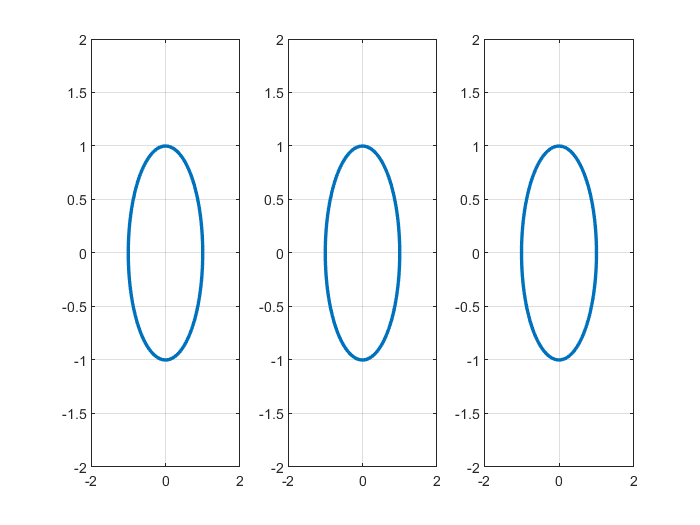

clear variables;
LW ='linewidth';
L = chebop(0, 10*pi);
L.op =@(t,x,y)[diff(x) - y; diff(y) + x];
for i = 1:3
    if i == 1
       L.lbc =@(x,y) [x; y-1];
       subplot(1,3,i)
    elseif i ==2
       L.lbc =@(x,y) [x; y+1];
       subplot(1,3,i)
    else
       L.lbc =@(x,y) [x+1; y];
       subplot(1,3,i)
    end
    rhs =[0;0];
    U=L\ rhs;
plot(U(1), U(2),LW,2);grid on
axis([-2 2 -2 2]);  
end 

Here with different initial conditions, but the trajectories are equivalent to each other.

2) $\left\lbrack x\left(0\right),y\left(0\right)\right\rbrack \;=\left\lbrack 0\ldotp 5\;,0\right\rbrack \;,\left\lbrack 0,\;2\right\rbrack ,\left\lbrack 2,0\right\rbrack$   

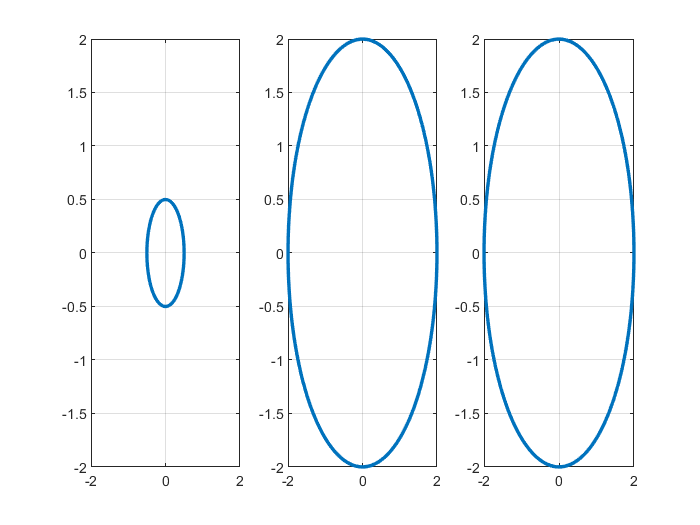

clear variables;
LW ='linewidth';
L = chebop(0, 10*pi);
L.op =@(t,x,y)[diff(x) - y; diff(y) + x];
for i = 1:3
    if i == 1
       L.lbc =@(x,y) [x-0.5; y];
        subplot(1,3,i)
    elseif i ==2
       L.lbc =@(x,y) [x; y-2];
        subplot(1,3,i)
    else
       L.lbc =@(x,y) [x-2; y];
        subplot(1,3,i)
    end
    rhs =[0;0];
    U=L\ rhs;
plot(U(1), U(2),LW,2);grid on ;
axis([-2 2 -2 2]);  
end 

Here the trajectories are circle with radius of initial points.Hence initial points length in the phase plane are different then the resultant trajectories are different.

**HW_2 :(Ex. 2.1 )**

   Given 

       
$${\dot{x} }_1 =-x_2 -\mu \;x_{1\;} \left(x_{1\;}^{2\;\;} +x_{2\;}^{2\;} \right)$$


        
$${\dot{x} }_2 =x_1 -\mu \;x_{1\;} \left(x_{1\;}^{2\;\;} +x_{2\;}^{2\;} \right)$$


Draw the trajectory of the solution in Ex.2.1 (pp. 35) with initial conditions as

    1) $\left\lbrack x_1 \left(0\right)\;,x_2 \left(0\right)\right\rbrack =\left\lbrack 1\;,0\right\rbrack$

    2) $\left\lbrack x_1 \left(0\right)\;,x_2 \left(0\right)\right\rbrack =\left\lbrack 0,1\right\rbrack$

    3) $\left\lbrack x_1 \left(0\right)\;,x_2 \left(0\right)\right\rbrack =\left\lbrack 1,1\right\rbrack$

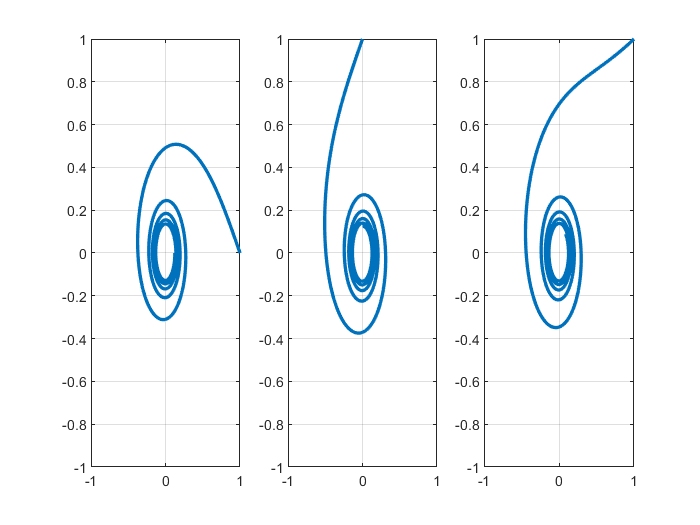

clear variables;
LW ='linewidth';
L = chebop(0, 10*pi);
mu = 1;
L.op =@(t,x,y)[diff(x) + y + mu*x*(x^2 + y^2);
    diff(y) - x + mu*y*(x^2 + y^2)];
for i = 1:3
    if i ==1
        L.lbc =@(x,y) [x-1; y];
         subplot(1,3,i)
    elseif i ==2
        L.lbc =@(x,y) [x; y-1];   
         subplot(1,3,i)
    else
        L.lbc =@(x,y) [x-1; y-1];   
         subplot(1,3,i)
    end
rhs =[0;0];
U=L\ rhs;
plot(U(1), U(2),LW,2);hold on ;grid on;
axis([-1 1 -1 1 ]);  
end
hold off

They are similar to stable focus.

**HW_3**

**Consider **

                  
$$\begin{array}{l}
\dot{x} =2x-\mathrm{xy}\\
\dot{y\;} =2x^2 -y
\end{array}$$


1) find equilibrium points

2) draw a phase plane

1) equilibrium points  $2x-\mathrm{xy}=0,2x^2 -y=0\;-\to y=2x^{2\;} -\to 2x-x\left(2x^2 \right)=0-\to x\left(1-x^{2\;} \right)=0$

Hence 


$$\left(x_{e\;,\;} y_e \right)=\left(0,0\right),\left(1,2\right),\left(-1,2\right)$$


2) phase plane

clear all;
L = chebop(@(t,x,y) [ diff(x)-2*x+x*y; diff(y)-2*x^2+y]);
quiver(L, [-2 2 0 3])
hold on
plot(0,0,'o')
hold off

You may see

   $\left(0,0\right)$: unstable

   (1,2) ; stable

   (-1,2); stable 

We may check to linearize the system as

     
$$\frac{\partial f}{\partial \;x\;}=\left\lbrack \begin{array}{cc}
2-y & 4x\\
-x & -1
\end{array}\right\rbrack \;$$


at $\left(0,0\right),\left(1,2\right),\left(-1,2\right)$ 

         
$$A_{x_{e\;} \;} =\left\lbrack \begin{array}{cc}
2 & 0\\
0 & -1
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
0 & 4\\
-1 & -1
\end{array}\right\rbrack \;,\left\lbrack \begin{array}{cc}
0 & -4\\
1 & -1
\end{array}\right\rbrack$$


where, unstable, stable focus and stable focus.

**HW_4**

**Given **

         
$$\ddot{y\;} \;-\mu \;\left(1-y^{2\;} \right)\dot{y\;} +y=0\;,t\in \left\lbrack 0,15\right\rbrack$$


 With different $\mu \;$ the trajectorise  are different,

1) state space 

         
$$\begin{array}{l}
\dot{x{\;}_1 } =x_{2\;} \\
\dot{x{\;}_2 } =\mu \;\left(1-x_1^2 \right)x_{2\;} -x_1 
\end{array}$$


2) It is local Lipschitz but not global Lipschitz due to squared term

3) Draw 

 3.1) oscillation when $\mu =0$

clear all;
L = chebop(@(t,x,y) [diff(x) - y; diff(y) - 0.125*(1-x^2)*y + x]);
quiver(L, [-2 2 -2 2],'normalize',0.2);


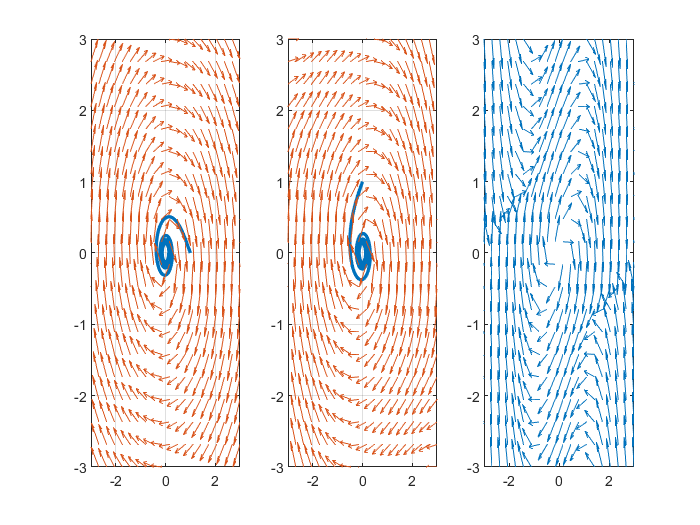

clear variables;
for i = 1:3
    if i ==1
        L = chebop(@(t,x,y) [diff(x) - y; diff(y) + x]);
        subplot(1,3,i)
        quiver(L, [-3 3 -3 3],'normalize',0.1);       
    elseif i ==2
        L = chebop(@(t,x,y) [diff(x) - y; diff(y) - 0.125*(1-x^2)*y + x]);
        subplot(1,3,i)
        quiver(L, [-3 3 -3 3],'normalize',0.1);        
    else
        L = chebop(@(t,x,y) [diff(x) - y; diff(y) - (1-x^2)*y + x]);
        subplot(1,3,i)
        quiver(L, [-3 3 -3 3],'normalize',0.1);          
    end
end

Looks difficult? We may get the solution with a specific initial conditions such as


$$\left(x\left(0\right),\dot{x} \left(0\right)\right)=\left(1,0\right),\left(3,0\right)$$


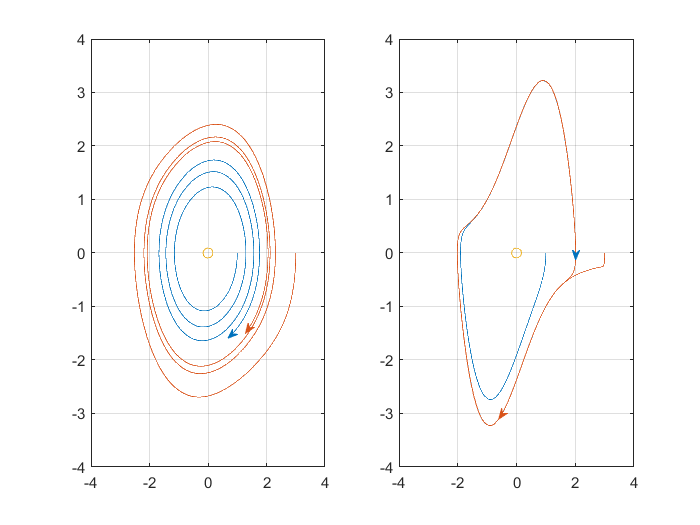

clear variables
N = chebop(0,20);
for j = 1:2
    subplot(1,2,j)
    mu = 0.125;
    if j ==2
        mu =1.5;
    end
    N.op=@(t,y) diff(y,2)- mu*(1-y^2)*diff(y)+y;
    for a =[1 3]
        N.lbc =[a;0];
        y = N\0;
        arrowplot(y, diff(y)); hold on; grid on   
        axis([-4 4 -4 4 ])
    end
    plot(0,0,'o')
end

Clearly you may see the limit cycle. 